# Matrix Inverse and Infinite Series

## Matrix Definitions

% Maths Tools: MATLAB Project
% Authors: Kadriye Nur Bakirci
%          Miguel Angel Guzman

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% PART 1.2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Matrix Inverse and Infinite Series
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% PURPOSE
% To see examples for which the matrix series I+C+C^2+. . .+C^k does
% converge to (I - C)-1 and examples for which it does not.
% Let the matrix C given by:
% 
%         1   |1 -1  5|
%    C = -- * |0  1 -2|
%        10   |1  3 -3|
%
% Type the following lines to calculate I + C + C2 + . . . + Ck for several
% values of k.
%                     I = eye(3); S = I;
%                     S = I + C - S

% -------------------------------------------------------------------------
% SECTION 1
% Use the up arrow key to execute the sum line repeatedly and watch to see 
% that this series does seem to converge.
% (The first time you execute this line, you get S = I + C;
% the second time you get I + C + C^2; etc.)
% How many times must you repeat it until the matrix S seems to stop
% changing, at least as far as what you see on the screen?

% Declaration of matrix C
C = 1/10 * [1 -1 5; 0 1 -2; 1 3 -3];

% Creation of Identity Matrix I3 (3x3)
I = eye(3);

% Declare matrix S and set it to a starting value of I3
S = I;

## Direct Computation of ${\left(I-C\right)}^{-1}$

% Series matrix should converge to (I-C)^-1, so it is computed for analysis
fprintf("Inverse matrix of (I-C):\n");

Inverse matrix of (I-C):


inv(I - C)

ans =     1.1604    0.0189    0.4434
   -0.0189    1.0566   -0.1698
    0.0849    0.2453    0.7642


## Computation of the Series $S=I+C+\mathrm{C2}+\ldotp \ldotp \ldotp +C^k$

% Declaration and assignment of 'k' value for the series
k = 13;

% Print analysis purpose for section
fprintf("S matrix analysis for each 'k' until k = %d.\n", k);

S matrix analysis for each 'k' until k = 13.



% Loop for different values of 'k' of the series equation
% Print matrix S in console each time to analyze matrix convergence
for i = 1 : k
    fprintf("Current k value: %d\n", i);
    % Series equation definition
    S = I + C * S
end

Current k value: 1


S =     1.1000   -0.1000    0.5000
         0    1.1000   -0.2000
    0.1000    0.3000    0.7000


Current k value: 2


S =     1.1600    0.0300    0.4200
   -0.0200    1.0500   -0.1600
    0.0800    0.2300    0.7800


Current k value: 3


S =     1.1580    0.0130    0.4480
   -0.0180    1.0590   -0.1720
    0.0860    0.2490    0.7600


Current k value: 4


S =     1.1606    0.0199    0.4420
   -0.0190    1.0561   -0.1692
    0.0846    0.2443    0.7652


Current k value: 5


S =     1.1603    0.0185    0.4437
   -0.0188    1.0568   -0.1700
    0.0850    0.2455    0.7639


Current k value: 6


S =     1.1604    0.0189    0.4433
   -0.0189    1.0566   -0.1698
    0.0849    0.2452    0.7642


Current k value: 7


S =     1.1604    0.0188    0.4434
   -0.0189    1.0566   -0.1698
    0.0849    0.2453    0.7641


Current k value: 8


S =     1.1604    0.0189    0.4434
   -0.0189    1.0566   -0.1698
    0.0849    0.2453    0.7642


Current k value: 9


S =     1.1604    0.0189    0.4434
   -0.0189    1.0566   -0.1698
    0.0849    0.2453    0.7641


Current k value: 10


S =     1.1604    0.0189    0.4434
   -0.0189    1.0566   -0.1698
    0.0849    0.2453    0.7642


Current k value: 11


S =     1.1604    0.0189    0.4434
   -0.0189    1.0566   -0.1698
    0.0849    0.2453    0.7642


Current k value: 12


S =     1.1604    0.0189    0.4434
   -0.0189    1.0566   -0.1698
    0.0849    0.2453    0.7642


Current k value: 13


S =     1.1604    0.0189    0.4434
   -0.0189    1.0566   -0.1698
    0.0849    0.2453    0.7642



% END OF SECTION 1
% -------------------------------------------------------------------------

Matrix S seems to stop changing by k=8.

## Analysis of the Norm of $\left(I-C\right)S-I$

% SECTION 2
% One way to check whether S is close to the inverse of (I - C) is to see
% whether the norm of (I - C)S - I is small. Experiment with different
% values of k to find how many terms of the series you must use in
%                  S = I + C + C^2 + . . . + C^k
% in order to get the norm of (I - C)S - I to be 10^-10 or smaller.

% Reset matrix S to value of I3
S = I;

% Re-assignment of 'k' value for the series
k = 17;

% Initialize an empty row vector of k elements to store norm results
y = zeros(1,k);

% Print analysis purpose for section
fprintf("Norm of (I-C)S-I analysis for each 'k' until k = %d.\n", k);

Norm of (I-C)S-I analysis for each 'k' until k = 17.



% Loop for different values of 'k' of the series equation
% Print norm of (I - C)S - I in console each time to analyze its size
for i = 1 : k
    fprintf("Current k value: %d\n", i);
    % Series equation definition
    S = I + C * S;
    % Variable to store/print the norm of (I - C)S - I for each k iteration
    n = norm((I-C) * S - I)
    % Store each norm value in the y-axis vector for plotting
    y(1,i) = n;
end

Current k value: 1


n = 0.2053

Current k value: 2


n = 0.0455

Current k value: 3


n = 0.0126

Current k value: 4


n = 0.0031

Current k value: 5


n = 8.0720e-04

Current k value: 6


n = 2.0297e-04

Current k value: 7


n = 5.2570e-05

Current k value: 8


n = 1.3374e-05

Current k value: 9


n = 3.4401e-06

Current k value: 10


n = 8.7897e-07

Current k value: 11


n = 2.2550e-07

Current k value: 12


n = 5.7709e-08

Current k value: 13


n = 1.4791e-08

Current k value: 14


n = 3.7874e-09

Current k value: 15


n = 9.7038e-10

Current k value: 16


n = 2.4854e-10

Current k value: 17


n = 6.3669e-11

By k=15 value is of 9.7038e-10

## Plot the norm of $\left.I-C\right)S-I$

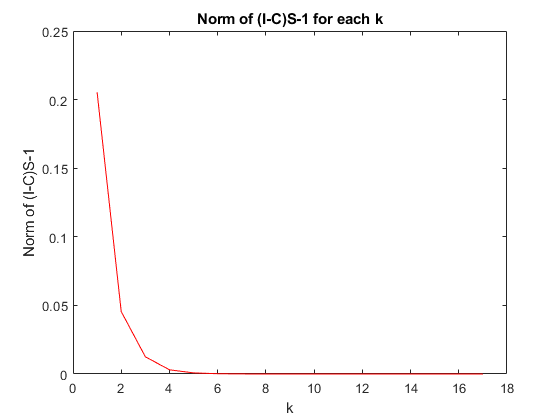

% Norm of (I-C)S-1 plot section
% Create x-axis row vector of k elements
x = [1:k];
%Select figure
figure(1)
% Display the plot
plot(x,y,'r')
title('Norm of (I-C)S-1 for each k')
xlabel('k')
ylabel('Norm of (I-C)S-1')


% END OF SECTION 2
% -------------------------------------------------------------------------

The plot shows an exponential decay for the norm of $\left.I-C\right)S-I$ given the increase of k-value.